We introduce our data and define I/O

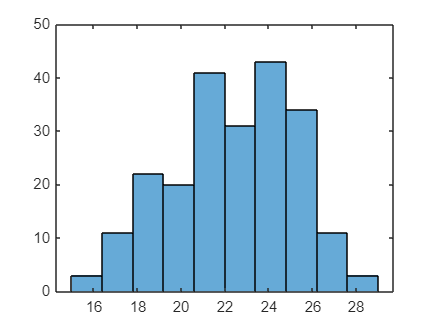

data = readmatrix('HorseShoe.csv');
inp = data(:,1:4);
out = data(:,5);
m = length(out);
%visualization of data%
histogram(out,10);

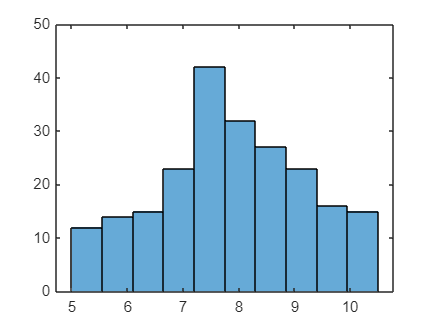

histogram(inp(:,4),10);

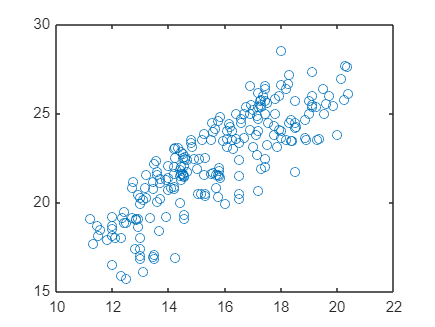

plot(inp(:,1),out,'o')

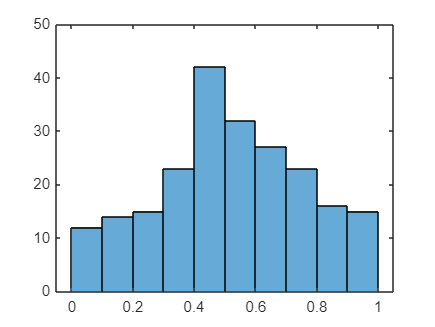

%Normalize the features in order to the inputs to have same weight and train more efficiently
% which will result in our inputs being in the range of 0 and 1 %
for i = 1:4
    normInp(:,i) = (inp(:,i)-min(inp(:,i)))/(max(inp(:,i))-min(inp(:,i)));
end
%Visualization%
histogram(normInp(:,4),10); 

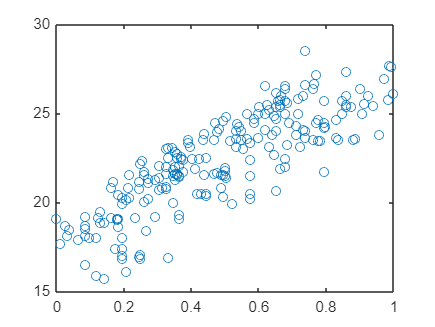

plot(normInp(:,1),out,'o');

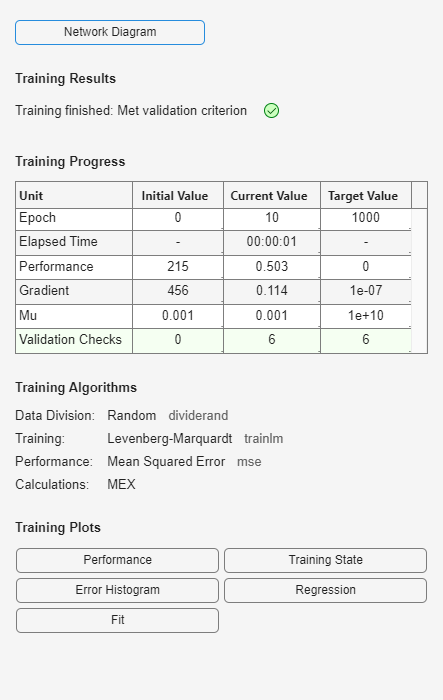

%Training%
normInp2 = normInp'; %We use the transposed form of input/output matrix in order to
%be able to use the train function 
out2 = out';
HiddenLayerSize = 7;
Network = fitnet(HiddenLayerSize); %use of fitnet function to build our ANN%
Network.divideParam.valRatio = 20/100; %We divide our data sets into 3 parts: training/test/validation
Network.divideParam.TrainRatio = 70/100;
Network.divideParam.testRatio = 10/100;
[Network, tr ] = train(Network, normInp2, out2); %training function%

%We test the performance of our ANN by calculatting the mean square error%
outputTrain = Network(normInp2(:,tr.trainInd));
outputRealTrain = out2(tr.trainInd);
sqrt((mean((outputTrain - outputRealTrain).^2))) %training RMSE%

ans = 0.7280

outputVal = Network(normInp2(:,tr.valInd));
outputRealVal = out2(tr.valInd);
sqrt((mean((outputVal - outputRealVal).^2))) %validation RMSE%

ans = 0.8078

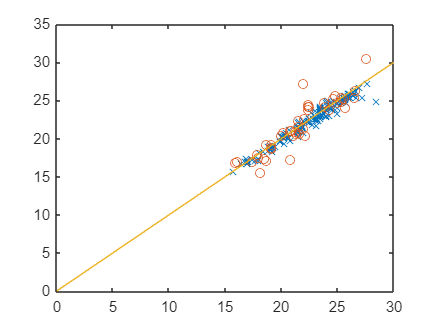

%   We visualize the accuracy of prediction results based on how close they
%   are to real results (how close they are to the x=y line)
plot(outputRealTrain,outputTrain,'x'); hold on 
plot(outputRealVal,outputVal,'o'); hold on 
plot(0:30,0:30); hold off

Optimize number of Neurons

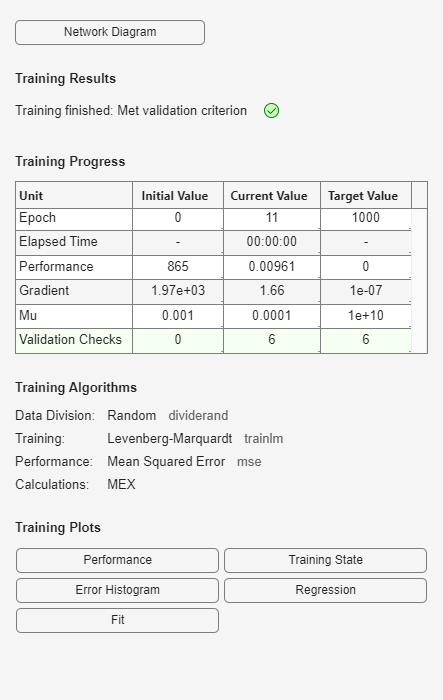

%As this ANN is only a shallow neural network and has only one layer, we
%make i an index vary from 1:100 to find the best number of neurons in this
%range
for i = 1:100
    HiddenLayerSize = i;
    Network = fitnet(HiddenLayerSize);
    Network.divideParam.valRatio = 20/100;
    Network.divideParam.TrainRatio = 70/100;
    Network.divideParam.testRatio = 10/100;
    [Network, tr ] = train(Network, normInp2, out2);
    outputTrain = Network(normInp2(:,tr.trainInd));
    outputVal = Network(normInp2(:,tr.valInd));
    outputRealTrain = out2(tr.trainInd);
    outputRealVal = out2(tr.valInd);
    mse_train(i) = sqrt((mean((outputTrain - outputRealTrain).^2))); %RMSE train%
    mse_val(i) = sqrt((mean((outputVal - outputRealVal).^2))); %RMse validation%
end

Choose best number of neurons

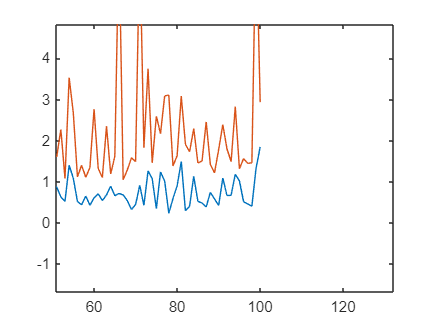

%we visualize evolution of mse according to number of neurons to optimize our ANN%
plot(1:100,mse_train); hold on
plot(1:100,mse_val); hold off

%We try our ANN on data sets unokwn to system %
outputTest = Network(normInp2(:,tr.testInd));
outputRealTest = out2(tr.testInd);
sqrt((mean((outputTest - outputRealTest).^2)))

ans = 0.6079

MAPE = mean(abs((outputRealTest - outputTest) ./ outputRealTest)) * 100

MAPE = 2.2436

%Finding mean absolute percentage error%